k1 = 0; %[N/m]
k2 = 20; %[N/m]
m0 = 13; %[Kg] unloaded mass
m1 = m0 + 23; %[Kg] loaded mass
g = 9.81; %[m/s^2]

z = [0:0.1:100]*1E-3%[mm] height variation

z =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


x0 = 2;
x = [1:0.1:2.5];
Lsides = sqrt(2);
L1_0 = x0 - 1;
L2_0 = x0 - 1;%prestreched springs

theta = real(acos((x/2)/Lsides))

theta =     1.2094    1.1713    1.1326    1.0932    1.0530    1.0118    0.9695    0.9260    0.8810    0.8342    0.7854    0.7341    0.6796    0.6212    0.5576    0.4867


%phi = real(asin((x/2)/Lsides))
L1 = 2*cos(theta)*Lsides;
L2 = 2*sin(theta)*Lsides;
F1 = (L1_0-L1) * k1

F1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


F2 =(L2_0-L2) * k2

F2 =   -32.9150  -32.1153  -31.2250  -30.2394  -29.1528  -27.9583  -26.6476  -25.2106  -23.6348  -21.9047  -20.0000  -17.8946  -15.5528  -12.9242   -9.9333   -6.4575


Fr = (F1 - F2/tan(theta))

Fr =    15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905   15.6905


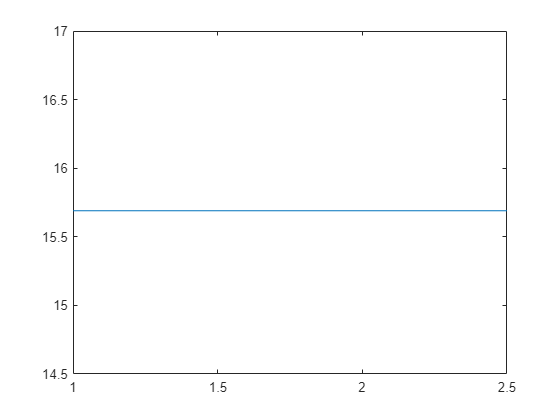

plot(x,Fr)